# Signal Processing of a Voice Signal

ECE 303 Final Project

**Ethan Bolt, Ryan Jones, and Connor Prikkel**

## Connor's Audio Signal

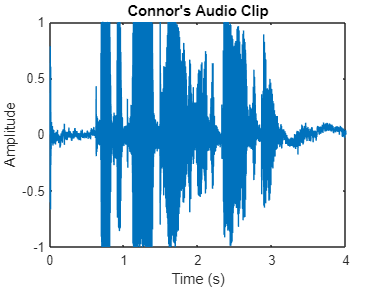

% Make a purge (courtesy of Stalin, Mao, Pot & Co.)
clear; close; clc;

% Import audio files and store voice signals
load conar_mao_quote.mat

sample_frequency = Fs;
connor_audio = y;

clear Fs y;
load ethan_mao_quote.mat
ethan_audio = y;

clear Fs y;
load ryan_mao_quote.mat
ryan_audio = y;
clear Fs y;

% Length of the audio in seconds
audio_duration = 4;

% Number of samples in the voice clip (also the length of the audio
% vectors)
sample_count = sample_frequency * audio_duration;

% Create vector for the time domain
t = linspace(0, sample_count / sample_frequency, sample_count);

plot_in_time_domain(t, connor_audio, "Connor's Audio Clip", [0 4 -1 1]);

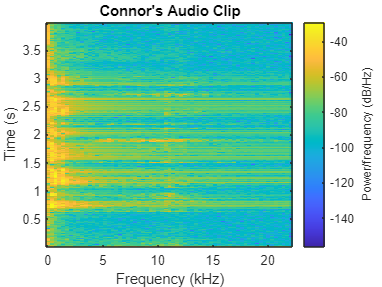

plot_spectrogram(sample_frequency, connor_audio, "Connor's Audio Clip");

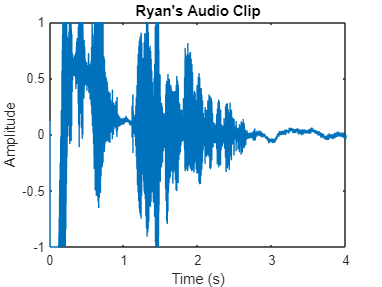


plot_in_time_domain(t, ryan_audio, "Ryan's Audio Clip", [0 4 -1 1]);

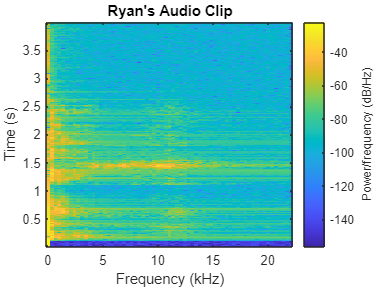

plot_spectrogram(sample_frequency, ryan_audio, "Ryan's Audio Clip");

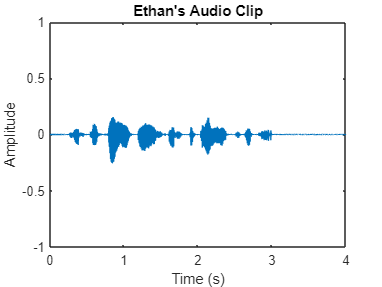


plot_in_time_domain(t, ethan_audio, "Ethan's Audio Clip", [0 4 -1 1]);

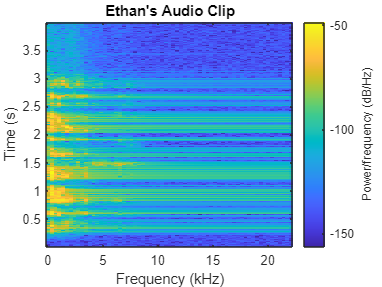

plot_spectrogram(sample_frequency, ethan_audio, "Ethan's Audio Clip");


fprintf("Power of Connor's audio clip: %.4f W", power(connor_audio));

Power of Connor's audio clip: 0.0599 W

fprintf("Power of Ryan's audio clip: %.4f W", power(ryan_audio));

Power of Ryan's audio clip: 0.0928 W

fprintf("Power of Ethan's audio clip: %.4f W", power(ethan_audio));

Power of Ethan's audio clip: 0.0004 W

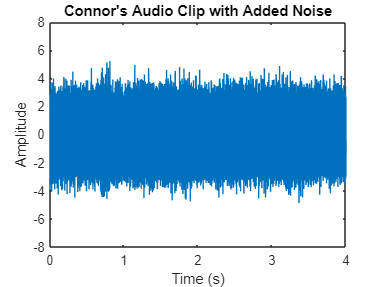


connor_noisy_audio = add_noise(t, connor_audio);
ryan_noisy_audio = add_noise(t, ryan_audio);
ethan_noisy_audio = add_noise(t, ethan_audio);

plot_in_time_domain(t, connor_noisy_audio, "Connor's Audio Clip with Added Noise", [0 4 -8 8]);

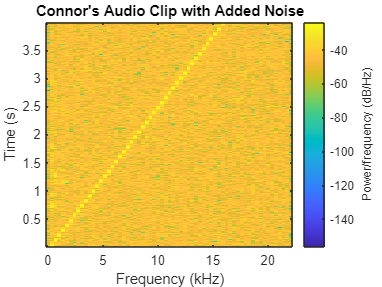

plot_spectrogram(sample_frequency, connor_noisy_audio, "Connor's Audio Clip with Added Noise");

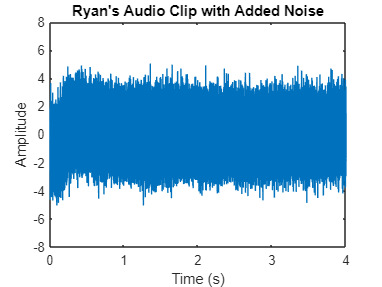


plot_in_time_domain(t, ryan_noisy_audio, "Ryan's Audio Clip with Added Noise", [0 4 -8 8]);

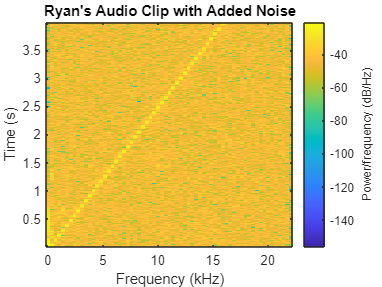

plot_spectrogram(sample_frequency, ryan_noisy_audio, "Ryan's Audio Clip with Added Noise");

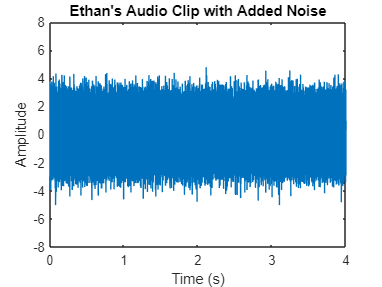


plot_in_time_domain(t, ethan_noisy_audio, "Ethan's Audio Clip with Added Noise", [0 4 -8 8]);

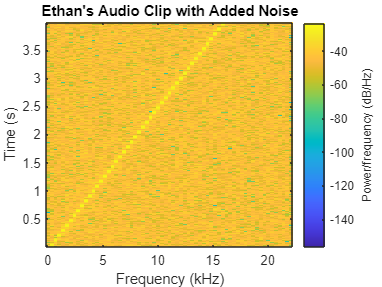

plot_spectrogram(sample_frequency, ethan_noisy_audio, "Ethan's Audio Clip with Added Noise");


fprintf("Power of Connor's audio clip with added noise: %.4f W", power(connor_noisy_audio));

Power of Connor's audio clip with added noise: 1.5175 W

fprintf("Power of Ryan's audio clip with added noise: %.4f W", power(ryan_noisy_audio));

Power of Ryan's audio clip with added noise: 1.6029 W

fprintf("Power of Ethan's audio clip with added noise: %.4f W", power(ethan_noisy_audio));

Power of Ethan's audio clip with added noise: 1.4337 W

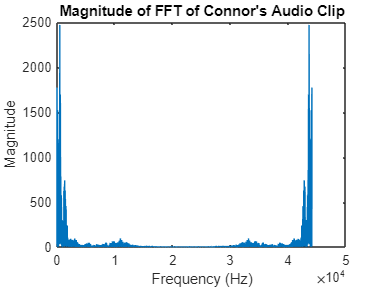

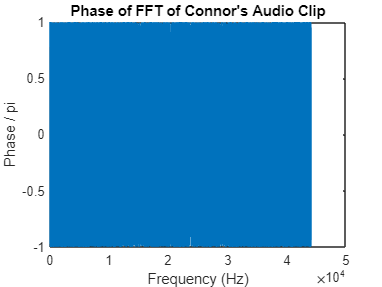


plot_fast_fouriers(connor_audio, sample_frequency, sample_count, "Magnitude of FFT of Connor's Audio Clip", "Phase of FFT of Connor's Audio Clip");

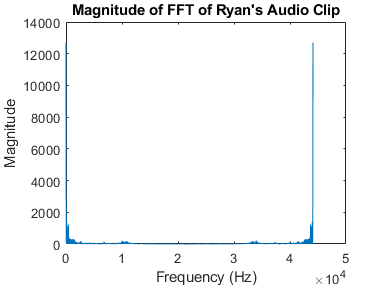

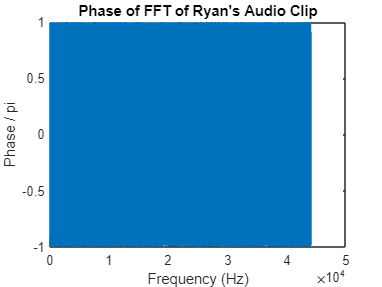

plot_fast_fouriers(ryan_audio, sample_frequency, sample_count, "Magnitude of FFT of Ryan's Audio Clip", "Phase of FFT of Ryan's Audio Clip");

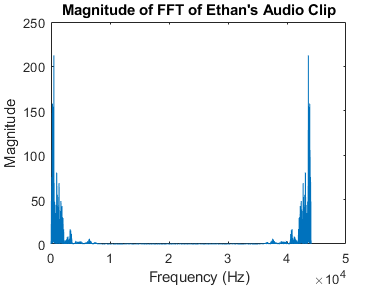

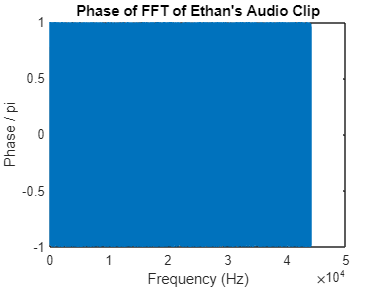

plot_fast_fouriers(ethan_audio, sample_frequency, sample_count, "Magnitude of FFT of Ethan's Audio Clip", "Phase of FFT of Ethan's Audio Clip");

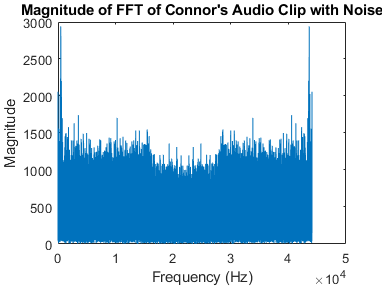

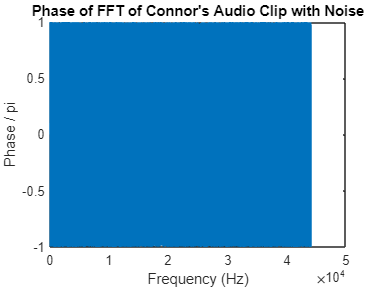


plot_fast_fouriers(connor_noisy_audio, sample_frequency, sample_count, "Magnitude of FFT of Connor's Audio Clip with Noise", "Phase of FFT of Connor's Audio Clip with Noise");

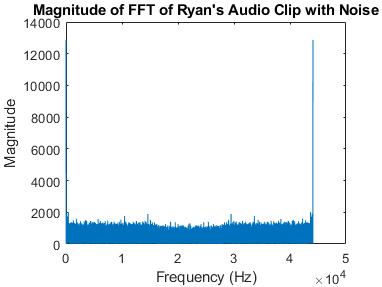

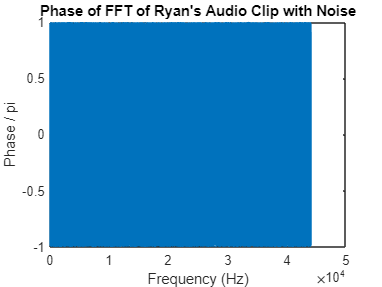

plot_fast_fouriers(ryan_noisy_audio, sample_frequency, sample_count, "Magnitude of FFT of Ryan's Audio Clip with Noise", "Phase of FFT of Ryan's Audio Clip with Noise");

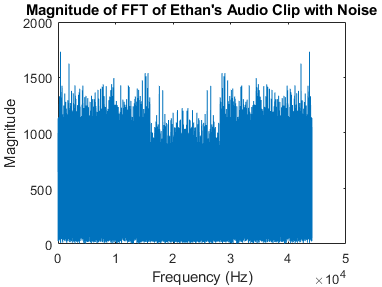

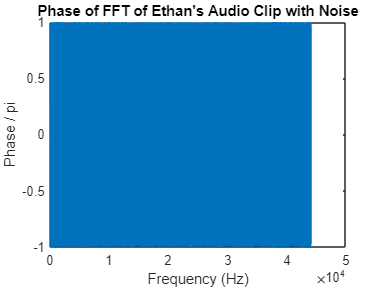

plot_fast_fouriers(ethan_noisy_audio, sample_frequency, sample_count, "Magnitude of FFT of Ethan's Audio Clip with Noise", "Phase of FFT of Ethan's Audio Clip with Noise");


%sampling frequency of .wav files
fs = 1/44100;



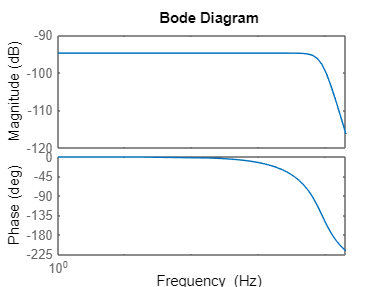

% % Chosen pass band frequency- based on highest significant freuqency in all
% % 3 input .mat files
% fp = 7500;
% 
% % Chebyshev frequency based upon chosen fp
% fc = 1.1675 * fp;
% 
% %cut-off frequency
% fct = 1e3;
% 
% % Constants for filers
% wp = 2 * pi * fp;
% wc = 2 * pi * fc;

% Chebyshev and Butterworth 3rd-order LPF transfer functions,
% using chosen pass band frequency.
%Hc  = @(s) (0.71750 * wp^3) / ((s + 0.62646 * wp) * (s^2 + 0.62646 * wp * s + 1.14245 * wp^2));
%Hb  = @(s) (wc^3) / ((s + wc) * (s^2 + s * wc + wc^2));
syms s;

wc = 55017605.63 / 1000;
butterworth_filter  = tf(wc, [1 wc wc^2]) * tf(wc, [1 wc]);

wp = wc / 1.1675;
chebyshev_filter    = tf(0.71570 * wp^2, [1 0.62646 * wp 1.41245 * wp^2]) * tf(wp, [1 wp]);

butterworth_plot    = bodeplot(butterworth_filter);
setoptions(butterworth_plot,'FreqUnits','Hz','XLimMode', 'manual', 'XLim', [1, 20000]);

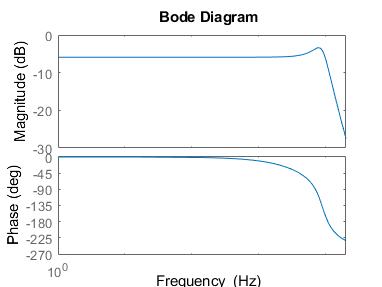


chebyshev_plot      = bodeplot(chebyshev_filter);
setoptions(chebyshev_plot,'FreqUnits','Hz','XLimMode', 'manual', 'XLim', [1, 20000]);

function plot_in_time_domain(t, y, title_str, limits)
    figure;
    plot(t, y);
    title(title_str);
    xlabel("Time (s)");
    ylabel("Amplitude");
    axis(limits);
end

function plot_spectrogram(sampling_frequency, y, title_str)
    spectrogram(y, rectwin(256), 120, 128, sampling_frequency);
    title(title_str);
end

function power = power(y)
    power = y' * y / length(y);
end

function noisy_signal = add_noise(t, y)
    % Generate a random SNR for the noise in (1, 0.01)
    snr = 10^( -2 * rand(1, 1) );

    % Add Gaussian noise to the input signal
    noisy_signal = awgn(y, snr, power(y));

    % Generate a 200 Hz to 16kHz chirp sweep
    chirp_noise = transpose(chirp(t, 200, t(end), 16e3));

    % Add it to the Gaussian noise
    noisy_signal = noisy_signal + chirp_noise;
end

function plot_fast_fouriers = plot_fast_fouriers(y, sampling_frequency, sampling_count, titlestr, titlestr2)
    % Take the fast fourier transform of signal
    fast_fourier = fft(y);

    % Compute the frequency of signal
    freq = 0:(sampling_frequency/sampling_count):(sampling_frequency-sampling_frequency/sampling_count);

    % Plot this frequency against the transform's magnitude
    plot(freq,abs(fast_fourier));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(titlestr);

    % Compute the phase of signal
    theta = angle(fast_fourier);

    % Plot frequency against transform's phase
    figure();
    plot(freq, theta/pi);
    xlabel('Frequency (Hz)');
    ylabel('Phase / pi');
    title(titlestr2);
end